%  PROVA DE SISTEMAS DE CONTROLE - SCRIPT DIDÁTICO DE APOIO

% Limpa o workspace, fecha figuras e limpa a tela de comando
clear; clc; close all;

% Define a variável 's' de Laplace para facilitar a criação de FTs
s = tf('s');

%  ========================================================================
%  Defina sua Função de Transferência (FT) aqui
%  ========================================================================
%{
    - Função de Transferência (FT): Usa-se os coeficientes dos polinômios do
      numerador e denominador. [cite_start]Lembre-se que G(s) = Saída(s)/Entrada(s)[cite: 1515].
      Os coeficientes devem ser VETORES-LINHA, em ordem decrescente de potência.
%}

% G(s) = 1000 / ((s+2)(s+3)(s+5))
% Denominador: (s^2 + 5s + 6)(s+5) = s^3 + 10s^2 + 31s + 30
num_G = [1000];
den_G = [1 10 31 30];
G = tf(num_G, den_G);

disp("Função de Transferência de Malha Aberta G(s):");

Função de Transferência de Malha Aberta G(s):


G


G =
 
            1000
  ------------------------
  s^3 + 10 s^2 + 31 s + 30
 
Continuous-time transfer function.


%{ ========================================================================
%  Defina seu Espaço de Estados (EE) aqui
%  ========================================================================
%{
    - Espaço de Estados (EE): Usa-se as matrizes A, B, C e D do modelo
      [cite_start]dx/dt = Ax + Bu, y = Cx + Du[cite: 1040, 1041].
%}

A = [-4 -5 -10; 1 0 0; 0 1 0];
B = [1; 0; 0];
C = [0 1 2];
D = 0;
sys_ss = ss(A, B, C, D);

disp("Sistema em Espaço de Estados sys_ss:");

Sistema em Espaço de Estados sys_ss:


sys_ss


sys_ss =
 
  A = 
        x1   x2   x3
   x1   -4   -5  -10
   x2    1    0    0
   x3    0    1    0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   0   1   2
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



%  ========================================================================
%  2. CONVERSÃO ENTRE MODELOS
%  ========================================================================
%{
    DIDÁTICA: O MATLAB automatiza as conversões.
    - De EE para FT: Ele calcula a fórmula T(s) = C(sI - A)^-1 * B + D.
    - De FT para EE: Ele cria uma representação em espaço de estados, geralmente na
      "forma canônica controlável", que é uma das várias representações possíveis.
%}
fprintf("\n>> 2. CONVERTENDO ENTRE MODELOS...\n");


>> 2. CONVERTENDO ENTRE MODELOS...


% Converter de FT para EE
sys_ss_from_G = ss(G);
disp("Sistema em EE obtido a partir de G(s):");

Sistema em EE obtido a partir de G(s):


sys_ss_from_G


sys_ss_from_G =
 
  A = 
          x1     x2     x3
   x1    -10  -7.75  -3.75
   x2      4      0      0
   x3      0      2      0
 
  B = 
       u1
   x1   8
   x2   0
   x3   0
 
  C = 
          x1     x2     x3
   y1      0      0  15.62
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


% Converter de EE para FT
G_from_sys_ss = tf(sys_ss);
disp("FT obtida a partir do sistema em EE:");

FT obtida a partir do sistema em EE:


G_from_sys_ss


G_from_sys_ss =
 
          s + 2
  ----------------------
  s^3 + 4 s^2 + 5 s + 10
 
Continuous-time transfer function.


%  ========================================================================
%  3. ANÁLISE DE MALHA FECHADA E DIAGRAMAS DE BLOCO
%  ========================================================================
%{
    DIDÁTICA: A principal operação é a de realimentação.
    A função feedback(G, H) calcula a fórmula de malha fechada:
    T(s) = G(s) / (1 + G(s)H(s)) para realimentação negativa.
    - G: Função de transferência do caminho direto.
    - H: Função de transferência do caminho de realimentação.
    - Para realimentação unitária, H = 1.
%}
fprintf("\n>> 3. CALCULANDO A FUNÇÃO DE TRANSFERÊNCIA DE MALHA FECHADA...\n");


>> 3. CALCULANDO A FUNÇÃO DE TRANSFERÊNCIA DE MALHA FECHADA...



% Defina um bloco H(s) para a realimentação, se não for unitária.
% Exemplo: H(s) = 1/(s+1)
H_num = [1];
H_den = [1 1];
H = tf(H_num, H_den);


% Malha Fechada com Realimentação Negativa
T = feedback(G, H, -1); % O -1 especifica realimentação negativa

disp("FT de Malha Fechada com H(s), T(s):");

FT de Malha Fechada com H(s), T(s):


T


T =
 
             1000 s + 1000
  -----------------------------------
  s^4 + 11 s^3 + 41 s^2 + 61 s + 1030
 
Continuous-time transfer function.


% Caso especial: Realimentação Unitária (H=1)
T_unitario = feedback(G, 1);

disp("FT de Malha Fechada Unitária, T_unitario(s):");

FT de Malha Fechada Unitária, T_unitario(s):


T_unitario


T_unitario =
 
             1000
  --------------------------
  s^3 + 10 s^2 + 31 s + 1030
 
Continuous-time transfer function.


% ========================================================================
%  4. ANÁLISE DE ESTABILIDADE
%  ========================================================================
%{
    DIDÁTICA: A estabilidade depende dos polos da função de MALHA FECHADA.
    - [cite_start]Polos no semiplano esquerdo (parte real < 0): Sistema estável[cite: 273].
    - [cite_start]Polos no semiplano direito (parte real > 0): Sistema instável[cite: 274].
    - [cite_start]Polos no eixo imaginário (parte real = 0): Sistema marginalmente estável[cite: 275].
%}
fprintf("\n>> 4. ANALISANDO A ESTABILIDADE DO SISTEMA EM MALHA FECHADA (T)...\n");


>> 4. ANALISANDO A ESTABILIDADE DO SISTEMA EM MALHA FECHADA (T)...



% --- Passo 1: Calcular os polos do sistema em malha fechada T(s) ---
polos = pole(T);
disp("Os polos do sistema em malha fechada são:");

Os polos do sistema em malha fechada são:


disp(polos);

  -6.8623 + 3.8222i
  -6.8623 - 3.8222i
   1.3623 + 3.8520i
   1.3623 - 3.8520i




% --- Passo 2: Interpretar a localização dos polos ---
if all(real(polos) < 0)
    disp("--> RESULTADO: O sistema é ESTÁVEL.");
else
    disp("--> RESULTADO: O sistema é INSTÁVEL ou MARGINALMENTE ESTÁVEL.");
end

--> RESULTADO: O sistema é INSTÁVEL ou MARGINALMENTE ESTÁVEL.


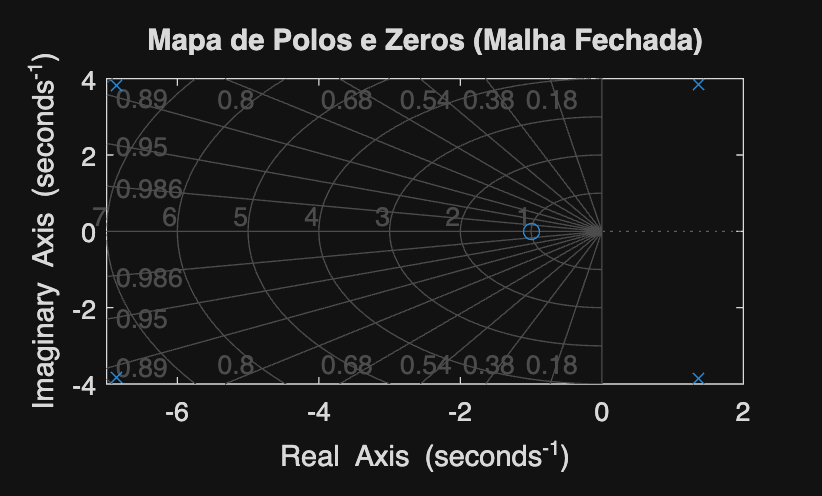


% Plotar o mapa de polos e zeros para visualização
figure('Name','Mapa de Polos e Zeros');
pzmap(T);
title('Mapa de Polos e Zeros (Malha Fechada)');
grid on;


%{
    DIDÁTICA: Critério de Routh-Hurwitz (Processo Manual)
    Este critério analisa o polinômio característico (denominador da FT em malha fechada)
    sem a necessidade de calcular os polos.
    
    COMO FAZER:
    1. Obtenha o polinômio característico. O código abaixo o exibe para você.
       D(s) = a_n*s^n + a_{n-1}*s^{n-1} + ... + a_1*s + a_0

    2. Monte as duas primeiras linhas da tabela de Routh:
       s^n     | a_n   a_{n-2}   a_{n-4} ...
       s^{n-1} | a_{n-1} a_{n-3}   a_{n-5} ...
       [cite_start][cite: 292, 304]

    3. Calcule os elementos das linhas seguintes. Por exemplo, para b1 na linha s^{n-2}:
       b1 = -det([a_n, a_{n-2}; a_{n-1}, a_{n-3}]) / a_{n-1}
       b1 = (a_{n-1}*a_{n-2} - a_n*a_{n-3}) / a_{n-1}
       [cite_start][cite: 330]

    4. INTERPRETAÇÃO: O número de trocas de sinal na primeira coluna da tabela é
       [cite_start]igual ao número de polos no semiplano direito (instáveis)[cite: 522].
%}
fprintf("\n--- Para o Critério de Routh-Hurwitz ---\n");


--- Para o Critério de Routh-Hurwitz ---


disp("Use os coeficientes do polinômio característico (denominador de T(s)):");

Use os coeficientes do polinômio característico (denominador de T(s)):


disp(T.Denominator{1});

           1          11          41          61        1030



%% ========================================================================
%  5. ERRO EM REGIME PERMANENTE (Para Realimentação Unitária)
%  ========================================================================
%{
    DIDÁTICA: O erro é calculado usando a função de MALHA ABERTA G(s) para
    sistemas com realimentação unitária[cite: 876]. O tipo do sistema (número de polos em s=0
    na malha aberta) define qual entrada terá erro finito.
%}
fprintf("\n>> 5. CALCULANDO O ERRO EM REGIME PERMANENTE (usando G(s))...\n");


>> 5. CALCULANDO O ERRO EM REGIME PERMANENTE (usando G(s))...



% --- Erro para Entrada Degrau (Posição) ---
% Fórmula: Kp = lim s->0 G(s)| ess = 1 / (1 + Kp)
Kp = dcgain(G);
ess_degrau = 1 / (1 + Kp);
fprintf("Constante de Posição Kp = %.4f\n", Kp);

Constante de Posição Kp = 33.3333


fprintf("Erro para entrada degrau e_ss = %.4f\n\n", ess_degrau);

Erro para entrada degrau e_ss = 0.0291




% --- Erro para Entrada Rampa (Velocidade) ---
% Fórmula: Kv = lim s->0 s*G(s) | ess = 1 / Kv [cite: 890]
syms s_sym
num_G_sym = poly2sym(cell2mat(G.Numerator), s_sym);
den_G_sym = poly2sym(cell2mat(G.Denominator), s_sym);
G_sym = num_G_sym / den_G_sym;

Kv = limit(s_sym * G_sym, s_sym, 0);
ess_rampa = 1 / Kv;
fprintf("Constante de Velocidade Kv = %.4f\n", double(Kv));

Constante de Velocidade Kv = 0.0000


fprintf("Erro para entrada rampa e_ss = %.4f\n\n", double(ess_rampa));

Erro para entrada rampa e_ss = Inf




% --- Erro para Entrada Parábola (Aceleração) ---
% Fórmula: Ka = lim s->0 s^2*G(s) | ess = 1 / Ka
Ka = limit(s_sym^2 * G_sym, s_sym, 0);
ess_parabola = 1 / Ka;
fprintf("Constante de Aceleração Ka = %.4f\n", double(Ka));

Constante de Aceleração Ka = 0.0000


fprintf("Erro para entrada parábola e_ss = %.4f\n\n", double(ess_parabola));

Erro para entrada parábola e_ss = Inf



%% ========================================================================
%  6. RESPOSTA TEMPORAL
%  ========================================================================
%{
    DIDÁTICA: As respostas temporais (degrau, impulso) são simuladas para o
    sistema em MALHA FECHADA (T), pois queremos ver o comportamento final
    do sistema controlado.
%}
fprintf(">> 6. GERANDO GRÁFICOS DE RESPOSTA TEMPORAL (usando T(s))...\n");

>> 6. GERANDO GRÁFICOS DE RESPOSTA TEMPORAL (usando T(s))...


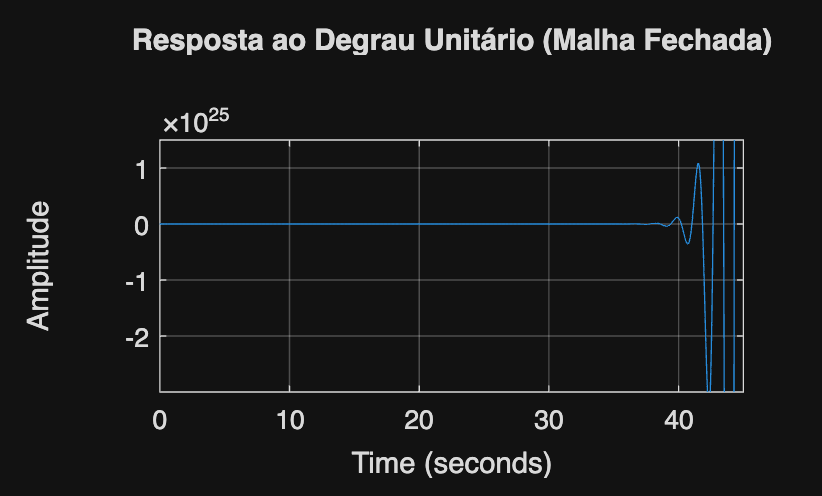


% Resposta ao Degrau
figure('Name','Resposta ao Degrau');
step(T);
title('Resposta ao Degrau Unitário (Malha Fechada)');
grid on;


% A função stepinfo calcula parâmetros importantes da resposta transitória
disp('Características da Resposta ao Degrau:');

Características da Resposta ao Degrau:


stepinfo(T)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: NaN
       Undershoot: NaN
             Peak: Inf
         PeakTime: Inf
